# PRÁCTICA 1 - DETECCIÓN AUTOMÁTICA DE EQUIPOS DE FUTBOL EN IMÁGENES

#### Tips y cosas:

- 30% de la Nota de Laboratorio

- Hay que probar RGB y HSV a ver que es mejor

- Mirar bien los bins de los histogramas para hacer la comparación

- Normalizar para hacer el problema más tratable

- Normalizar HSV => Eliminar V

- Tantos histogramas para el modelo como hagan falta: 2 o 3 => Para variar las posibilidades de histograma: Mucho blaugrana, poco blaugrana, etc

- Probar a hacer recortes aleatorios, toda la imagen, etc...

- Para la comparación la distribución de color tiene que ser significativamente igual.

- Se puede utilizar automaización de detección de formas de camiseta.

- Comparación de histogramas (de vecindad): Mínimos Cuadrados (post filtrado gaussiano), Chi-Square.

- Histograma 3-dimensional (con tripletas, no histograma 3D)

- Reducir los colores: Cada 4, 8 16 niveles de rojo, azul, verde => Para que coincidan los histogramas.

- Se puede aplicar normalización de color => Obtenemos una aplicación más tolerante a cambios de color y nos podemos cargar una componente => Histograma bidimensional.

## Global Definitions

### Barça Model

bins = 128;

bcnImageModel1 = imagePreProcessingRGB(imread('./soccer/models/39.jpg'));
bcnImageModel2 = imagePreProcessingRGB(imread('./soccer/models/42.jpg'));
bcnImageModel3 = imagePreProcessingRGB(imread('./soccer/models/43.jpg'));

histModelRGB1 = histogramRGB(bcnImageModel1, bins);
histModelRGB2 = histogramRGB(bcnImageModel2, bins);
histModelRGB3 = histogramRGB(bcnImageModel3, bins);

histModelHSV1 = histogramHSV(bcnImageModel1, bins);
histModelHSV2 = histogramHSV(bcnImageModel2, bins);
histModelHSV3 = histogramHSV(bcnImageModel3, bins);

% 3 modelos a, b, c => a*0.2 + b*0.4 + c*0.6
bcnModelRGB = {{histModelRGB1, histModelRGB2, histModelRGB2}, {0.2, 0.4, 0.6}};
bcnModelHSV = {{histModelHSV1, histModelHSV2, histModelHSV3}, {0.2, 0.4, 0.6}};

% dist_X < bcn__Threshold => True (is Barça)
bcnRGBThreshold = 0.1; % TO DO
bcnHSVThreshold = 0.1; % TO DO

## Experiments

imagesMilan = getTeamImages('./soccer/acmilan/', '*.jpg', false);
imagesChelsea = getTeamImages('./soccer/chelsea/', '*.jpg', false);
imagesJuventus = getTeamImages('./soccer/juventus/', '*.jpg', false);
imagesLiverpool = getTeamImages('./soccer/liverpool/', '*.jpg', false);
imagesMadrid = getTeamImages('./soccer/madrid/', '*.jpg', false);
imagesPSV = getTeamImages('./soccer/psv/', '*.jpg', false);
imagesBarcelona = getTeamImages('./soccer/barcelona/', '*.jpg', false);

allImages = getAllImages('./soccer/', '*.jpg', false)
bins = 128
bcnRGBThreshold = calculateThreshold(bcnModelRGB, imagesBarcelona, allImages, 1, bins, @compareChiDistance)

% ---------------------------------------- EXPERIMENTS AREA ----------------------------------------

dirs = 10×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


allImages = 1×240 cell array
    {273×400×3 uint8}    {450×300×3 uint8}    {450×348×3 uint8}    {450×329×3 uint8}    {245×300×3 uint8}    {245×300×3 uint8}    {300×300×3 uint8}    {250×350×3 uint8}    {393×470×3 uint8}    {290×350×3 uint8}    {268×270×3 uint8}    {350×266×3 uint8}    {348×400×3 uint8}    {307×440×3 uint8}    {268×400×3 uint8}    {410×305×3 uint8}    {268×384×3 uint8}    {227×300×3 uint8}    {150×200×3 uint8}    {262×384×3 uint8}    {384×303×3 uint8}    {211×150×3 uint8}    {180×180×3 uint8}    {252×300×3 uint8}    {290×300×3 uint8}    {328×455×3 uint8}    {325×455×3 uint8}    {392×280×3 uint8}    {210×310×3 uint8}    {250×180×3 uint8}    {254×410×3 uint8}    {474×304×3 uint8}    {160×260×3 uint8}    {348×250×3 uint8}    {242×220×3 uint8}    {282×550×3 uint8}    {170×310×3 uint8}    {217×340×3 uint8}    {320×205×3 uint8}    {220×340×3 uint8}    {234×398×3 uint8}    {420×354×3 uint8}    {182×275×3 uint8}    {160×300×3 uint8}    {400×226×3 uint8}    {206×241×3 uint8}    {

bins = 128

histogramsTeam = 1×40 cell array
    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}


histogramsNotTeam = 1×240 cell array
    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}   

resultsTeam =     0.4180    0.4082    0.5421    0.4012    0.3231    0.3813    0.5293    0.4993    0.4670    0.4725    0.4886    0.7784    0.4987    0.5877    0.5389    0.3481    0.2902    0.4956    0.5055    0.4921    0.5071    0.5783    0.4568    0.4237    0.5646    0.4861    0.3884    0.2674    0.5549    0.4245    0.2587    0.4960    0.3310    0.2971    0.5038    0.5245    0.5400    0.6318    0.2752    0.4059


resultsNotTeam =     0.4953    0.4370    0.5427    0.5102    0.5611    0.4252    0.4951    0.5393    0.5349    0.3991    0.5153    0.5881    0.5832    0.6028    0.6571    0.5466    0.7143    0.5097    0.5637    0.5126    0.5556    0.5269    0.5667    0.5435    0.5154    0.3941    0.5296    0.5821    0.5756    0.6223    0.6832    0.4907    0.5901    0.4857    0.5521    0.4546    0.6042    0.6525    0.3135    0.6521    0.6876    0.5608    0.6431    0.5726    0.5665    0.4465    0.6000    0.5311    0.4264    0.5801


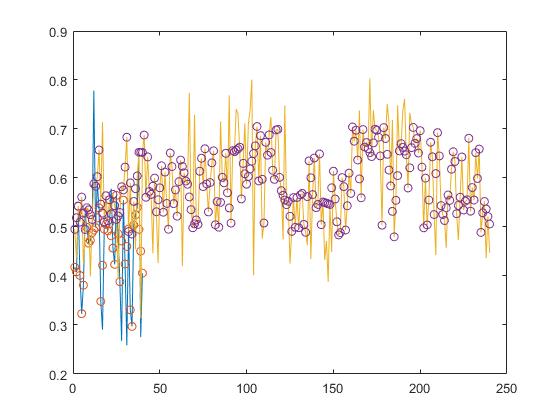

t = 0.5223

bcnRGBThreshold = 0.5223

% Example of use of the experiments function:

experiments(allImages, imagesBarcelona, bins, @imagePreProcessingRGB, @histogramRGB, containers.Map({'models', 'threshold'}, {bcnModelRGB, bcnRGBThreshold}), @compareChiDistance);
% Note that we should choose just imagesMilan, distance function and the color model of bcnModelRGB and bcnRGBThreshold.
% All else depend on the model parametrization.



Results table:


results = 1×240 cell array
    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 doub

Positive cases:
Image 1: 0.49532
Image 2: 0.43695
Image 4: 0.51016
Image 6: 0.42523
Image 7: 0.49509
Image 10: 0.3991
Image 11: 0.51532
Image 18: 0.50973
Image 20: 0.51257
Image 25: 0.51536
Image 26: 0.39406
Image 32: 0.49072
Image 34: 0.48574
Image 36: 0.4546
Image 39: 0.31347
Image 46: 0.44647
Image 49: 0.42639
Image 55: 0.49537
Image 60: 0.52205
Image 63: 0.41992
Image 69: 0.49847
Image 71: 0.51439
Image 72: 0.50517
Image 82: 0.50462
Image 84: 0.49951
Image 91: 0.50789
Image 104: 0.40147
Image 109: 0.47639
Image 110: 0.50814
Image 121: 0.47453
Image 125: 0.42538
Image 126: 0.49101
Image 128: 0.49934
Image 130: 0.4984
Image 133: 0.50534
Image 134: 0.48908
Image 135: 0.46266
Image 137: 0.43465
Image 143: 0.50483
Image 145: 0.43259
Image 146: 0.47133
Image 147: 0.38841
Image 149: 0.44872
Image 152: 0.51073
Image 153: 0.48388
Image 154: 0.48849
Image 157: 0.49389
Image 178: 0.50366
Image 185: 0.47993
Image 202: 0.49829
Image 204: 0.50428
Image 209: 0.44264
Image 214: 0.51322
Image 215: 

results = 1×40 cell array
    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}


Positive cases:
Image 1: 0.41795
Image 2: 0.40823
Image 4: 0.40115
Image 5: 0.32309
Image 6: 0.38134
Image 8: 0.49929
Image 9: 0.46704
Image 10: 0.47252
Image 11: 0.4886
Image 13: 0.49869
Image 16: 0.34808
Image 17: 0.29024
Image 18: 0.49563
Image 19: 0.50547
Image 20: 0.49209
Image 21: 0.5071
Image 23: 0.45679
Image 24: 0.42366
Image 26: 0.48609
Image 27: 0.38839
Image 28: 0.2674
Image 30: 0.42451
Image 31: 0.25874
Image 32: 0.49599
Image 33: 0.33101
Image 34: 0.29706
Image 35: 0.50379
Image 39: 0.27523
Image 40: 0.40585
Total positive cases: 29
Negative cases:
Image 3: 0.54209
Image 7: 0.52935
Image 12: 0.77843
Image 14: 0.58775
Image 15: 0.53893
Image 22: 0.57832
Image 25: 0.56461
Image 29: 0.55489
Image 36: 0.52452
Image 37: 0.54002
Image 38: 0.63182
Total negative cases: 11


**Function to calculate the optimal threshold to diferentiate between two classes, images of the team, and images that aren't of that team **

- teamModels: model to which the distance is calculated

- imagesTeam: train set of images of the team to calculate the threshold

- imagesNotTeam: train set of images not of the team to calculate the threshold

- rgbOrHsv: boolean to indicate if the threshold to calculate is with RGB histogram or HSV histogram

- bins: number of bins to calculate the histograms

- distF: distance function  

function t = calculateThreshold(teamModels, imagesTeam, imagesNotTeam, rgbOrHsv, bins, distF)
    n = size(imagesTeam);
    m = size(imagesNotTeam);

    % Obtaining histogram of preprocessed images
    histogramsTeam = cell(1, n(2));
    histogramsNotTeam = cell(1, m(2));
    for i=1:n(2)
        % rgbOrHsv: 1 rgb, 0 hsv
        if(rgbOrHsv)
            histogramsTeam{i} = histogramRGB(imagePreProcessingRGB(imagesTeam{i}), bins);
        else
            histogramsTeam{i} = histogramHSV(imagePreProcessingHSV(imagesTeam{i}), bins);
        end
    end
    
    for i=1:m(2)
        if(rgbOrHsv)
            histogramsNotTeam{i} = histogramRGB(imagePreProcessingRGB(imagesNotTeam{i}), bins);
        else
            histogramsNotTeam{i} = histogramHSV(imagePreProcessingHSV(imagesNotTeam{i}), bins);
        end
    end
    histogramsTeam, histogramsNotTeam
    resultsTeam = zeros(n(2), 0);
    resultsNotTeam = zeros(m(2), 0);
    for i = 1:n(2)
        dist = calculateDistance(teamModels, histogramsTeam{i}, distF);
        resultsTeam(i) = dist;
    end
    for i = 1:m(2)
        dist = calculateDistance(teamModels, histogramsNotTeam{i}, distF);
        resultsNotTeam(i) = dist;
    end
    resultsTeam, resultsNotTeam
    % Here calculate the threshold
    
    resultsTeamWithoutOutliers = filloutliers(resultsTeam,'linear', 'percentiles', [10 90]);
    resultsNotTeamWithoutOutliers = filloutliers(resultsNotTeam,'linear', 'percentiles', [10 90]);
    plot(1:n(2),resultsTeam,1:n(2),resultsTeamWithoutOutliers,'o')
    hold on
    plot(1:m(2),resultsNotTeam,1:m(2),resultsNotTeamWithoutOutliers,'o')
    hold off
    t = (max(resultsTeamWithoutOutliers) + min(resultsNotTeamWithoutOutliers))/2
end

## **Functions**

    **Function to get all the images (in the same format) from a directory**:

- selector == true: Do not specify the path (dirBase), a browser opens on a base direction (dirBase)

- selector == false: Specify the absolute path or a relative path to the 'Current Folder).           

function images = getTeamImages(dirBase, format, selector)
    d = '';
    if (selector)
        d = uigetdir(pwd, dirBase);
    else
        d = dirBase;
    end

    files = dir(fullfile(d, format));
    
    [rows cols] = size(files);
    images = cell(1,rows);
    for i=1:rows
        image_file = imread(strcat(files(i).folder, '/', files(i).name));
        images{i} = image_file;
    end
end

function images = getAllImages(dirBase, format, selector)
    d = '';
    if (selector)
        d = uigetdir(pwd, dirBase);
    else
        d = dirBase;
    end
    
    dirs = dir(d)
    [rows cols] = size(dirs);
    images = cell(1,40 * (rows-4));
    k = 1;
    for i=1:size(dirs)
        if (~strcmp(dirs(i).name, 'barcelona') && ~strcmp(dirs(i).name, 'models')...
                && ~strcmp(dirs(i).name, '.') && ~strcmp(dirs(i).name, '..'))
            files = dir(fullfile(strcat(d, dirs(i).name, '/'), format));
            
            [rows cols] = size(files);
            for j=1:rows
                image_file = imread(strcat(files(j).folder, '/', files(j).name));
                images{k} = image_file;
                k = k + 1;
            end
        end
    end
end

    **Image preprocessing functions (RGB and HSV)**:

% RGB preprocessing
function impp = imagePreProcessingRGB(im)
    % Image components extraction
    r = im(:,:,1);
    g = im(:,:,2);
    b = im(:,:,3);
    
    % Color normalization
    I = double(r) + double(g) + double(b);
    Rn = double(r) ./ I;
    Gn = double(g) ./ I;
    Bn = double(b) ./ I;
    
    impp = uint8(cat(3, Rn, Gn, Bn) * 255);
end

% HSV preprocessing
function img = imagePreProcessingHSV(im)
    img = uint8(rgb2hsv(im) * 1000);
end

**    Euclidean Distance (L2) function**:

function result = compareEuclideanDistance(hist1, hist2)
    [n m] = size(hist1);
    dist = 0;
    for i=1:n
        for j=1:m
            aux = (hist1(i, j) - hist2(i, j));
            dist = dist + (aux*aux);
        end
    end
    result = sqrt(dist);
end

    **Chi-Square Distance function**:

function result = compareChiDistance(hist1, hist2)
    hist1 = imgaussfilt(hist1,2);
    hist2 = imgaussfilt(hist2,2);
    [n m] = size(hist1);
    dist = 0;
    for i=1:n
        for j=1:m
            aux = hist1(i, j) - hist2(i, j);
            if (hist1(i, j) + hist2(i, j) > 0)
                dist = dist + (aux*aux)/(hist1(i, j) + hist2(i, j));
            end
        end
    end
    result = dist / 2;
end

    **Bidimensional Histogram (without Green/V component) functions (RGB and HSV)**:

% RGB Histogram
function h = histogramRGB(im, bins)
    R = im(:,:,1);
    %G = im(:,:,2);
    B = im(:,:,3);

    h = zeros(bins, bins);
    [n m] = size(R);
    for i = 1:n
        for j = 1:m
            r = floor(R(i, j)/ (256/bins)) + 1;
            b = floor(B(i, j)/ (256/bins)) + 1;
            if (r > 128) 
                r = r - 1;
            end
            if (b > 128)
                b = b - 1;
            end
            h(r, b) = h(r, b) + 1;
        end
    end
    h = h ./ (n*m);
end

%HSV Histogram
function hist = histogramHSV(im, bins)
    H = im(:,:,1);
    S = im(:,:,2);
    %V = im(:,:,3);
    
    hist = zeros(bins, bins);
    [n m] = size(H);
    for i = 1:n
        for j = 1:m
            h = mod(H(i, j), bins) + 1;
            s = mod(S(i, j), bins) + 1;
            
            hist(h, s) = hist(h, s) + 1;
        end
    end
    
    % histogram normalization
    hist = hist ./ (n*m);
end

    **Function to check if in a given histogram there are some team (for example: barça):**

- models: Matrix of pairs (image model histogram in RGB/HSV).

- hist: Image histogram to check (in the same color model as models).

- distF: Function to compute te distance.

- threshold: Distances < threshold will not belong to the team

function [is dist] = isTeam(models, hist, distF, threshold)
    dist = 0.0;
    sumPond = 0.0;
    [n m] = size(models);
   
    for i = 1:n
        dist = dist + models{2}{i} * distF(hist, models{1}{i});
        sumPond = sumPond + models{2}{1};
    end
    
    dist = dist/sumPond;
    is = dist < threshold;
end

**Function to calculate the distance between a certain histogram and a sum of ponderated models**

- models: Matrix of pairs (image model histogram in RGB/HSV).

- hist: Image histogram to check (in the same color model as models).

- distF: Function to compute te distance.

function dist = calculateDistance(models, hist, distF)
    dist = 0.0;
    sumPond = 0.0;
    [n m] = size(models);
    
    for i = 1:n
        dist = dist + models{2}{i} * distF(hist, models{1}{i});
        sumPond = sumPond + models{2}{1};
    end
    
    dist = dist/sumPond;
end

    **Function to carry out the experiments**:

- hsitoBins: Bins to compute te histogram.

- isTeamParameters: Models and threshold of the function isTeam.

- distF: Distance function.

function results = experiments(imgs, imgs2, histoBins, preprocessingF, histogramF, isTeamParameters, distF)
    [n m] = size(imgs);
    
    % Obtaining histogram of preprocessed images
    histograms = cell(1, m);
    for i=1:m
        histograms{i} = histogramF(preprocessingF(imgs{i}), histoBins);
    end
    
    % Compute results (output)
    results = cell(1,m);
    for i = 1:m
        [is dist] = isTeam(isTeamParameters('models'), histograms{i}, distF, isTeamParameters('threshold'));
        results{i} = [is dist];
    end
    
    % Show results
    disp('Results table:');
    results
    
    % Print positive cases
    disp('Positive cases:');
    countPos = 0;
    for i = 1:m
        if (results{1,i}(1))
            disp(['Image ', num2str(i), ': ',  num2str(results{1,i}(2))]);
            countPos = countPos + 1;
        end
        
    end
    disp(['Total positive cases: ', num2str(countPos)]);
    
    % Print negative cases
    disp('Negative cases:');
    countNeg = 0;
    for i = 1:m
        if (~results{1,i}(1))
            disp(['Image ', num2str(i), ': ',  num2str(results{1,i}(2))]);
            countNeg = countNeg + 1;
        end  
    end
    disp(['Total negative cases: ', num2str(countNeg)]);
    
    
    
    
    
    [n m] = size(imgs2);
   % Obtaining histogram of preprocessed images
    histograms = cell(1, m);
    for i=1:m
        histograms{i} = histogramF(preprocessingF(imgs2{i}), histoBins);
    end
    
    % Compute results (output)
    results = cell(1,m);
    for i = 1:m
        [is dist] = isTeam(isTeamParameters('models'), histograms{i}, distF, isTeamParameters('threshold'));
        results{i} = [is dist];
    end
    
    % Show results
    disp('Results table:');
    results
    
    % Print positive cases
    disp('Positive cases:');
    countPos = 0;
    for i = 1:m
        if (results{1,i}(1))
            disp(['Image ', num2str(i), ': ',  num2str(results{1,i}(2))]);
            countPos = countPos + 1;
        end
        
    end
    disp(['Total positive cases: ', num2str(countPos)]);
    
    % Print negative cases
    disp('Negative cases:');
    countNeg = 0;
    for i = 1:m
        if (~results{1,i}(1))
            disp(['Image ', num2str(i), ': ',  num2str(results{1,i}(2))]);
            countNeg = countNeg + 1;
        end  
    end
    disp(['Total negative cases: ', num2str(countNeg)]);
end